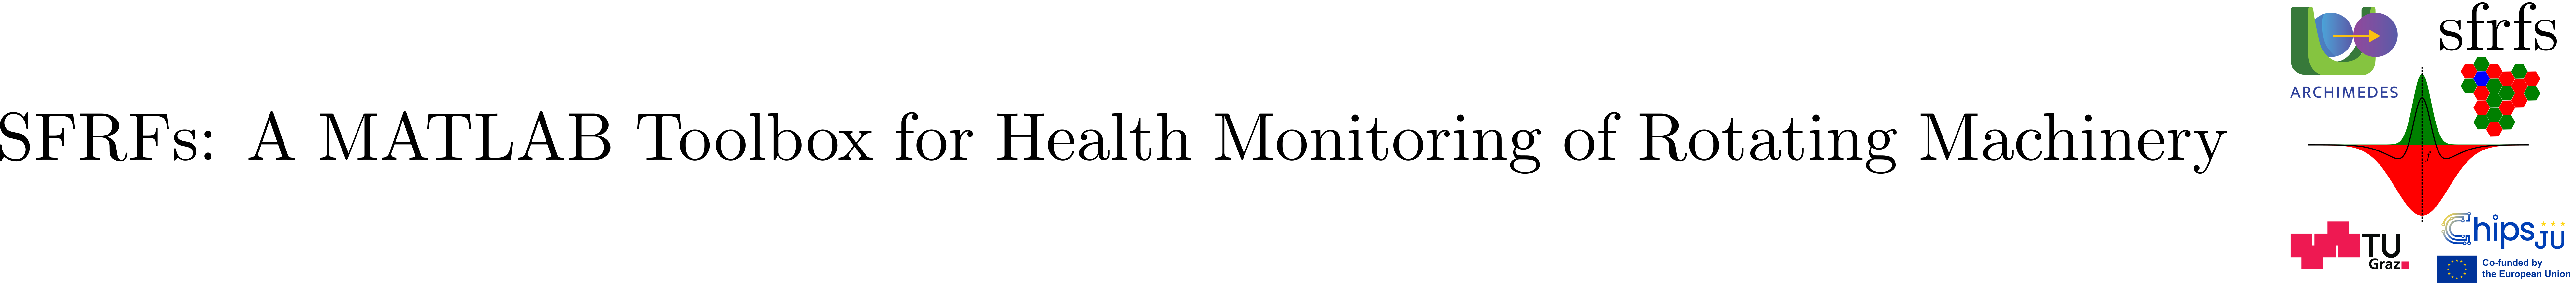

# SFRFsEnsembleBroker

## Summary

`SFRFsEnsembleBroker` is a concrete subclass of [`EnsembleBroker`](matlab:open('./EnsembleBroker.mlx')) tailored for Spectral Fault Receptive Field (SFRF) operations. It extends the base ensemble-brokering functionality by introducing SFRF-specific column naming logic while preserving the generic, metadata-aware handling of ensemble member files.

**Key features:**

- Inherits all ensemble management, metadata handling, and file retrieval capabilities from `EnsembleBroker`.

- Introduces a configurable SFRF suffix (default: `"_SFRFs"`) for consistent naming of SFRF-derived columns.

- Provides explicit mapping methods between temporal column names and their corresponding SFRF column names.

- Supports standardized and unambiguous handling of SFRF representations within ensemble processing workflows.

## Description

`SFRFsEnsembleBroker` is a concrete subclass of [`EnsembleBroker`](matlab:open('./EnsembleBroker.mlx')) that adds support for Spectral Fault Receptive Field (SFRF) naming within ensemble workflows. It preserves all generic ensemble handling functionality while introducing a dedicated convention for identifying SFRF-derived columns.

The class defines an internal SFRF suffix, configurable at construction time, which is appended to temporal column names to generate their corresponding SFRF identifiers. Two utility methods, `mapToSFRFColumn` and `mapToTemporalFromSFRFColumn`, provide bidirectional mapping between temporal and SFRF column representations. This localized extension maintains a clear separation between generic ensemble operations and SFRF-specific logic, ensuring consistency across the processing pipeline.

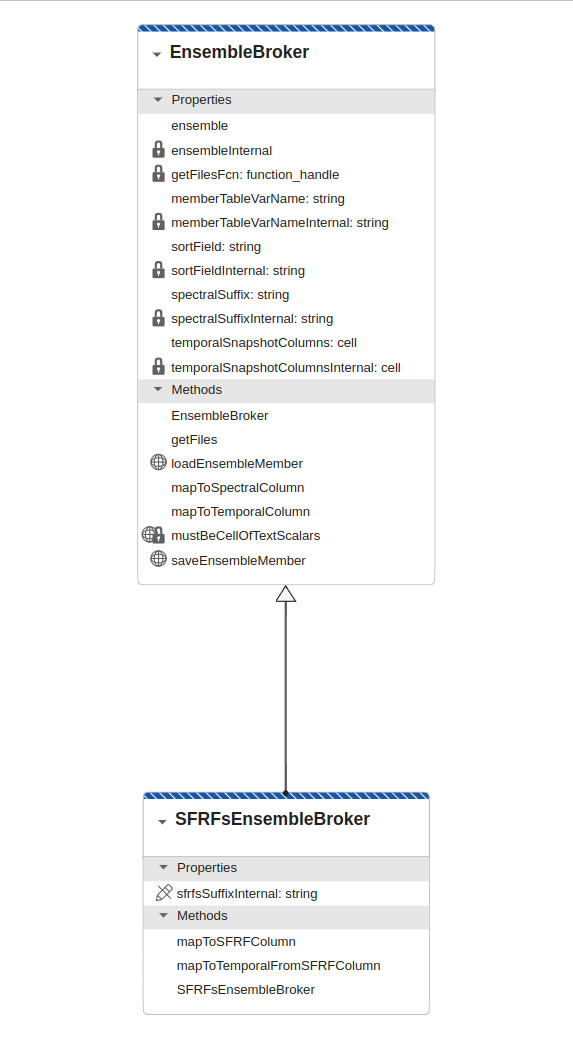

**Figure 1**. SFRFsEnsembleBroker extends EnsembleBroker.

Figure 1 shows the inheritance relationship of this class with [`EnsembleBroker`](matlab:open('./EnsembleBroker.mlx')), we refer the reader to the superclass documentation for further detals in the inherited properties.

### Public methods

### Constructor

The constructor `SFRFsEnsembleBroker` accepts the following name–value arguments:

## Example

We obtain a fileEnsembleDatastore object for the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset (see Reference [1]). For a procedure to compute the ensemble from the dataset see [createXJTUSYEnsemble](matlab:open('./createXJTUSYEnsemble.mlx')).

% Obtain a handle to an existing ensemble by selecting its folder via GUI.
% This creates a configured fileEnsembleDatastore without loading any data.
ensemble = data.getXJTUSYEnsemble();

% Define the columns with raw accelerometer signals
temporalSnapshotColumns = {...
    'HorizontalAcceleration', 'VerticalAcceleration'};

% Initialize the ensemble broker with the obtained ensemble
broker = SFRFsEnsembleBroker( ...
    EnsembleObject=ensemble, ...
    GetFilesFunction=@(obj) obj.Files, ...
    TemporalSnapshotColumns=temporalSnapshotColumns)

broker =   SFRFsEnsembleBroker with properties:

        sfrfsSuffixInternal: "_SFRFs"
                   ensemble: [1×1 fileEnsembleDatastore]
                  sortField: "SnapshotIndex"
         memberTableVarName: "ensembleMemberTable"
    temporalSnapshotColumns: {'HorizontalAcceleration'  'VerticalAcceleration'}
             spectralSuffix: "_FFT"


## API documentation

### MATLAB help

help SFRFsEnsembleBroker

  SFRFSENSEMBLEBROKER  EnsembleBroker specialization for SFRF data.
 
    SFRFsEnsembleBroker extends EnsembleBroker by introducing a dedicated
    naming convention for Spectral Fault Receptive Field (SFRF) columns. In
    addition to the temporal and spectral (FFT) mappings provided by the
    superclass, this class defines and manages an SFRF-specific suffix for
    consistent identification of SFRF-derived signals.
 
    Key features:
      • Inherits full ensemble management, metadata handling, and file
        retrieval capabilities from EnsembleBroker.
      • Adds a configurable SFRF suffix (default: "_SFRFs").
      • Provides bidirectional mapping between temporal and SFRF column 
        names.
 
    See also: EnsembleBroker, EnsembleUtil

    Documentation for SFRFsEnsembleBroker
       doc SFRFsEnsembleBroker




### MATLAB documentation

doc SFRFsEnsembleBroker

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Test

Unit testing for the class is implemented in [TestSFRFsEnsembleBroker](matlab:open('../../../tests/TestSFRFsEnsembleBroker.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestSFRFsEnsembleBroker');

Running TestSFRFsEnsembleBroker
....
Done TestSFRFsEnsembleBroker
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestSFRFsEnsembleBroker/testDefaultSFRFsSuffix                                   | Passed
TestSFRFsEnsembleBroker/testCustomSFRFsSuffix                                    | Passed
TestSFRFsEnsembleBroker/testMappingPreservesType                                 | Passed
TestSFRFsEnsembleBroker/testTemporalMappingErrorsIfSuffixMissing                 | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).